clear
close all
clc
delete(gcp('nocreate'))
tic


## load data and functions


DIR ='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/';
spec='Results_dock_time/Initial_vel_fluid/';
loadDIR=[DIR spec];

% Declare constants, load functions and data
Const = Constants;
fDIR='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/Functions/';
addpath(fDIR)

load([loadDIR 'Dock_time_eps_00001_inorbit_katy.mat'])


## choose plot parameters


% choose plot type
typ=0;  % 0- z eps do r_orb
        % 1- z r_s do eps,

% how many St/A cases - plots in one figure
ile=15;
%
fsize=16;
width=20;
height=25;

%skalowanie: 0- nie, 1- tak
skal=1;

% co_ile shows how many lines in a group we want to omit, 0-plot all the
% lines, 1- remove every line (no sense), 2 - remove every second line, 3-remove every third line etc.
co_ile=2;

## data manipulation

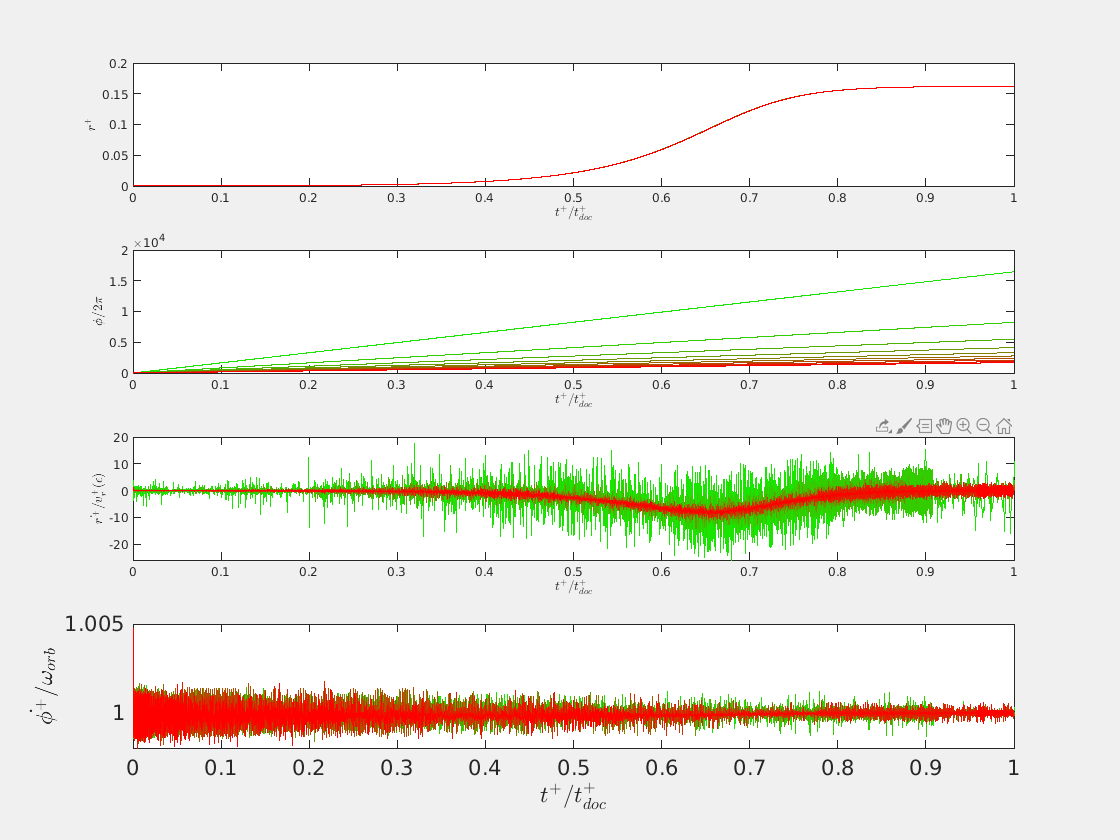


switch typ
    case 1
        r0=1.58499;
    case 0
        r0=0;
end

% choose relevant St/A values (for respective docking process)
wybor=[];
param=zeros(1,numel(part));
for p=1:numel(part)
    param(p)=part(p).par.A^(-1)*part(p).par.St;
    if abs(part(p).init.r0_bez-r0)<=eps && imag(texit(p))==0 && ~isnan(texit(p))
        wybor=[wybor,p];
    end
end

param_wyb=param(wybor);
parmin=min(param_wyb);
parmax=max(param_wyb);
St_wyb=St(wybor);
A_wyb=A(wybor);
% group
%choose grouping parameter
P_wyb=round(St_wyb./A_wyb);
kol_odn=St; % parameter for colorscale
%find groups of the same par. value
[P_id,Pgr]=findgroups(P_wyb);
for k=1:numel(Pgr)
    ids{k}=find(P_id==k);
    ids_nr(k)=numel(ids{k});
end
najliczniejsze=nonzeros((ids_nr>1).*(1:numel(Pgr)));

figure
set(gcf,'Visible','on')
set(gcf,'Position', [640, 300, 2*560, 2*420 ],...
    'paperunits','centimeters',...
    'papersize',[width,height],...
    'InvertHardCopy','off')
 set(gca,'FontSize',fsize)
 
for p=1:numel(najliczniejsze)
    clf
    k=najliczniejsze(p);
    numerki=wybor(ids{k});
    numerki(1:co_ile:end)=[];
    maxt=max(texit(numerki));
    Plot_docking_trajectory
    pause(2)
end